clc 
clear all

s = zpk('s');
sample_time = 1e-3;

G = ss(0.036*(s+25.28)/(s^2*(s^2+0.0396*s+1)));
Gd = c2d(G,sample_time);
systemnames='Gd';

% inputvar='[d;n;r;u]';
% outputvar='[Gd+d-r;u;r-n-d-Gd]';
inputvar='[r;u]';
outputvar='[Gd-r;r-Gd]';
input_to_Gd='[u]';
P=sysic;

K = ss(7.9212*(s+0.1818)*(s^2-0.2244*s+0.8981)/((s^2+3.899*s+4.745)*(s^2+1.039*s+3.395)));
Kd = c2d(K,sample_time);
P_star_K=ss(lft(P,Kd));
isstable(P_star_K)

ans = logical
   1


G = Gd;
K = Kd;


G = Gd;
K = Kd;

S = (1 + G*K)^-1;
T = 1-S;

[A,B,C,D] = ssdata(G);
N = 3;
[G, d] = get_G(A,B,C,D,zeros(length(A),1), N);
l = length(B(1,:));
m = length(C(:,1));

do_plot = 1;
Q = eye(m*N+1);
R = eye(l*(N+1));

u0 = .1*ones(l*(N+1),1);
r = rand(m*(N+1),1);


do_plot = 1;
beta = .5;
%[u_inf1, e_inf1, y_inf1, impr1, iteration_number1] = IA(G,d, beta,r, u0, R, Q,do_plot, 1)
%title('Inverse model algorithm')
figure
[u_inf2, e_inf2, y_inf2, impr2, iteration_number2] = SDA(G,d, beta,r, u0, R, Q, do_plot)

G_star =    1.0e-09 *

   (1,1)       0.0060
   (1,2)       0.0426
   (2,2)       0.0060
   (1,3)       0.1165
   (2,3)       0.0426
   (3,3)       0.0060
   (1,4)       0.2286
   (2,4)       0.1165
   (3,4)       0.0426
   (4,4)       0.0060


currErrordiff:


ans = 2.2208e-05

currErrordiff:


ans = 3.1995e-06

u_inf2 = 1×5201 cell array
  Columns 1 through 624

    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    

e_inf2 = 1×5201 cell array
  Columns 1 through 714

    {[0.8059]}    {[0.8045]}    {[0.8032]}    {[0.8019]}    {[0.8006]}    {[0.7994]}    {[0.7982]}    {[0.7970]}    {[0.7959]}    {[0.7948]}    {[0.7937]}    {[0.7926]}    {[0.7915]}    {[0.7905]}    {[0.7895]}    {[0.7885]}    {[0.7875]}    {[0.7865]}    {[0.7855]}    {[0.7846]}    {[0.7837]}    {[0.7827]}    {[0.7818]}    {[0.7809]}    {[0.7800]}    {[0.7792]}    {[0.7783]}    {[0.7774]}    {[0.7766]}    {[0.7757]}    {[0.7749]}    {[0.7741]}    {[0.7732]}    {[0.7724]}    {[0.7716]}    {[0.7708]}    {[0.7700]}    {[0.7692]}    {[0.7684]}    {[0.7676]}    {[0.7668]}    {[0.7660]}    {[0.7652]}    {[0.7644]}    {[0.7637]}    {[0.7629]}    {[0.7621]}    {[0.7613]}    {[0.7606]}    {[0.7598]}    {[0.7591]}    {[0.7583]}    {[0.7576]}    {[0.7568]}    {[0.7561]}    {[0.7553]}    {[0.7546]}    {[0.7538]}    {[0.7531]}    {[0.7523]}    {[0.7516]}    {[0.7509]}    {[0.7501]}    {[0.7494]}    {[0.7486]}    {[0.7479]}    {[0.7472]}    {[0.74

y_inf2 = 1×5201 cell array
  Columns 1 through 624

    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    {4×1 double}    

impr2 = 26.2932

iteration_number2 = 26003

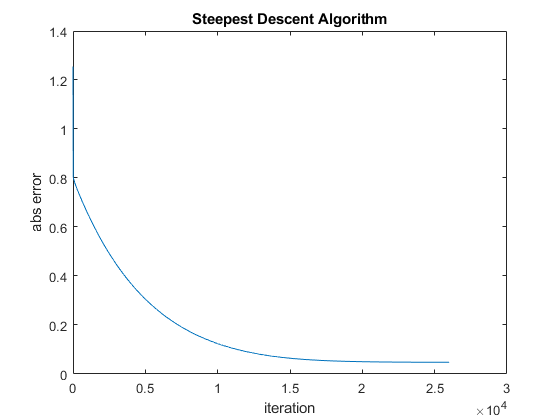

title('Steepest Descent Algorithm')
ylabel('abs error');
xlabel('iteration');

figure
[u_inf3, e_inf3, y_inf3, impr3, iteration_number3] = SDA_suppression_of_evs(G,d, r, u0, R, Q,do_plot)

currErrordiff:


ans = 2.0605e-05

currErrordiff:


ans = 2.9687e-06

u_inf3 = 	1.0e+11 *

    0.3568
   -1.1757
    1.4557
    0.4418


e_inf3 = 0.0477

y_inf3 =     0.2154
    0.8090
    0.0296
    0.9284


impr3 = 26.2932

iteration_number3 = 25617

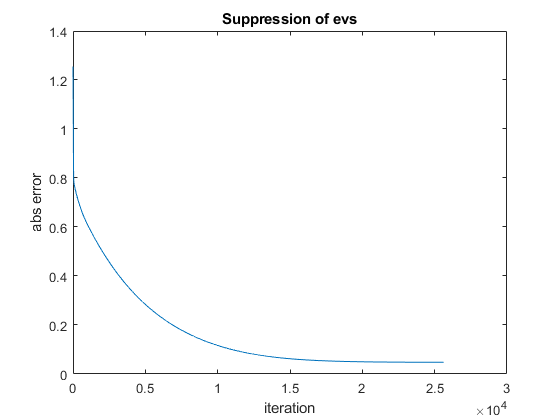

title('Suppression of evs')
ylabel('abs error');
xlabel('iteration');

figure






[A,B,C,D] = ssdata(K);
[Kc, dc] = get_G(A,B,C,D,zeros(length(A),1), N);

[A,B,C,D] = ssdata(S);
[S, ds] = get_G(A,B,C,D,zeros(length(A),1), N);

[A,B,C,D] = ssdata(T);
[T, dt] = get_G(A,B,C,D,zeros(length(A),1), N);

Ku = Kc*S*T';
Ke = T*T';


% 
% 
% [A,B,C,D] = ssdata(K*S*T');
% [Ku, du] = get_G(A,B,C,D,zeros(length(A),1), N);
% 
% [A,B,C,D] = ssdata(T*T');
% [Ke, de] = get_G(A,B,C,D,zeros(length(A),1), N);

beta = 1/norm(Ke);



u = u0;
e0 = r - G*u - d; 
e = e0;
cont = 1;
iteration_number = 0;
error_history = [norm(e0)]; 
input_history = [norm(u0)];

u_inf = {};
e_inf = {};
y_ing = {};
cell_nb = 0;
while cont
    iteration_number = iteration_number + 1;
    u_new = u + beta*Ku*e;
    e_new = (eye(length(e0)) - beta*Ke)*e;
    
    if norm(e - e_new)<10^-6
        cont = 0;
    end
    error_history = [error_history, norm(e_new)];
    input_history = [input_history, norm(u_new)];
    if(mod(iteration_number, 10000) == 0)
        disp("currErrordiff:")
        norm(e_new - e)
    end
    u = u_new;
    e = e_new;
    
    if mod(iteration_number,5) == 0
        cell_nb = cell_nb + 1;
        u_inf{cell_nb} = u_new;
        e_inf{cell_nb} = norm(e_new);
        y_inf{cell_nb} = G*u_new + d;
    end
end

currErrordiff:


ans = 8.0079e-06

currErrordiff:


ans = 5.3821e-06

currErrordiff:


ans = 3.6173e-06

currErrordiff:


ans = 2.4312e-06

currErrordiff:


ans = 1.6340e-06

currErrordiff:


ans = 1.0982e-06

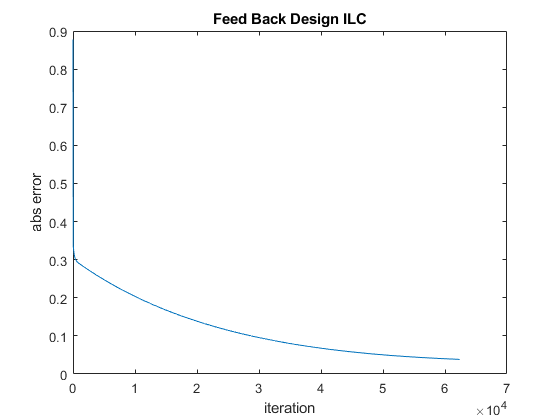


if mod(iteration_number,5) ~= 0
        cell_nb = cell_nb + 1;
        u_inf{cell_nb} = u_new;
        e_inf{cell_nb} = norm(e_new);
        y_inf{cell_nb} = G*u_new + d;
end

impr = norm(e0)/e_inf{length(e_inf)};

if do_plot
    plot(0:iteration_number, error_history);
    ylabel('abs error');
    xlabel('iteration');
    title('Feed Back Design ILC');
end

cd Examples
load('FBDesign')
cd ..
plot(0:iteration_number, error_history);
ylabel('abs error');
xlabel('iteration');
title('Feed Back Design ILC');